clear

load('savedvars/matfile.mat')

x = [];
for i = 1:length(possible_states)
    x(i) = possible_states{i,1}(1);
end

y = [];
for i = 1:length(possible_states)
    y(i) = possible_states{i,1}(2);
end

z = [];
for i = 1:length(possible_states)
    z(i) = possible_states{i,1}(3);
end

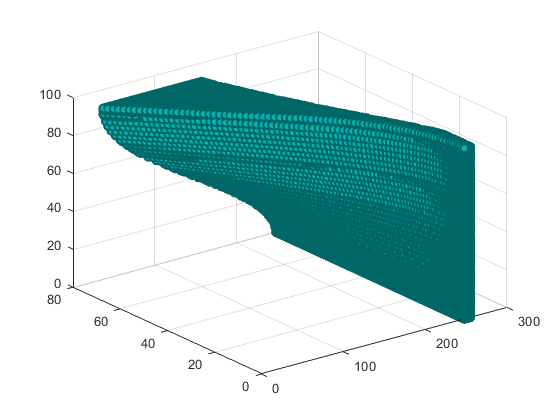

scatter3(x,y,z,'MarkerEdgeColor',[0 .4 .4], 'MarkerFaceColor',[0 .7 .7], 'LineWidth', 1.5)

xlbounds = [];
for i = 1:length(lower_bound)
    xlbounds(i) = lower_bound{i,1}(1);
end

ylbounds = [];
for i = 1:length(lower_bound)
    ylbounds(i) = lower_bound{i,1}(2);
end

zlbounds = [];
for i = 1:length(lower_bound)
    zlbounds(i) = lower_bound{i,1}(3);
end

xubounds = [];
for i = 1:length(upper_bound)
    xubounds(i) = upper_bound{i,1}(1);
end

yubounds = [];
for i = 1:length(upper_bound)
    yubounds(i) = upper_bound{i,1}(2);
end

zubounds = [];
for i = 1:length(upper_bound)
    zubounds(i) = upper_bound{i,1}(3);
end

xbounds = [];
for i = 1:length(bounds)
    xbounds(i) = bounds{i,1}(1);
end

ybounds = [];
for i = 1:length(bounds)
    ybounds(i) = bounds{i,1}(2);
end

zbounds = [];
for i = 1:length(bounds)
    zbounds(i) = bounds{i,1}(3);
end

xmbounds = [];
for i = 1:length(optim_slice)
    xmbounds(i) = optim_slice{i,1}(1);
end

ymbounds = [];
for i = 1:length(optim_slice)
    ymbounds(i) = optim_slice{i,1}(2);
end

zmbounds = [];
for i = 1:length(optim_slice)
    zmbounds(i) = optim_slice{i,1}(3);
end

xsbounds = [];
for i = 1:length(sim)
    xsbounds(i) = sim{i,1}(1);
end

ysbounds = [];
for i = 1:length(sim)
    ysbounds(i) = sim{i,1}(2);
end

zsbounds = [];
for i = 1:length(sim)
    zsbounds(i) = sim{i,1}(3) * 180/pi;
end

ind = cat(1, zmbounds, ymbounds).'

ind =    17.0000  265.7344
   17.0000  264.0753
   17.0000  262.4139
   17.0000  260.7500
   17.0000  259.0837
   17.0000  257.4149
   17.0000  255.7435
   17.0000  254.0696
   17.0000  252.3931
   17.0000  250.7140


model = polyfitn(ind, xmbounds.', 5);

% scatter3(xbounds,ybounds,zbounds,'MarkerEdgeColor',[0 .4 .4], 'MarkerFaceColor',[0 .7 .7], 'LineWidth', 1.5)
% hold on
% scatter3(xmbounds, ymbounds, zmbounds, 'MarkerFaceColor',[.4 .0 .0], 'MarkerEdgeColor',[.4 .4 .6])
% fsurf(@(x,y) polyvaln(model, [x y]), "c")
% zlim([0 100])
% ylim([0 90])
% xlim([130 300])
% hold off

scatter3(zmbounds, ymbounds, xmbounds, 'MarkerFaceColor', [.4 .8 .8], 'MarkerEdgeColor', "none", "MarkerFaceAlpha",0.3)
hold on
fsurf(@(x,y) polyvaln(model, [x y]))

model.R2

ans = 0.9999

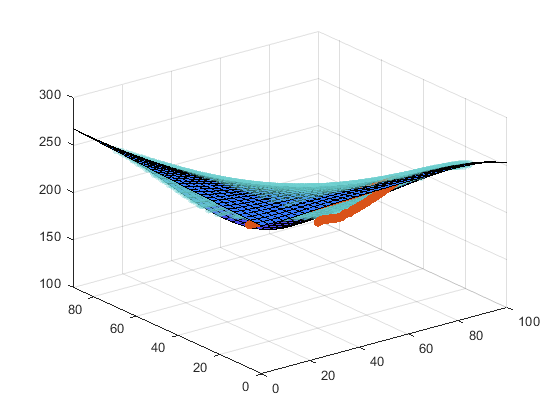


scatter3(zsbounds, ysbounds, xsbounds)
xlim([0 100])
ylim([0 90])
zlim([100 300])
hold off

% model.p
Coefficients = model.Coefficients

Coefficients =    -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0007    0.0000   -0.0000   -0.0002    0.0239   -0.0000    0.0000   -0.0001   -0.0120   -0.2214    0.0000    0.0000   -0.0000    0.0008    0.0839  256.4758


ModelTerms = model.ModelTerms

ModelTerms =      5     0
     4     1
     4     0
     3     2
     3     1
     3     0
     2     3
     2     2
     2     1
     2     0


save("savedvars/optimal_surface","ModelTerms","Coefficients")

polyvaln(model, [50, 20])

ans = 242.6416

sim{1}

ans =   120.7537
   73.7492
    1.5304
    0.0100
